# Following code snippets are written in the best effort to simulate various methods, phenomenons, conditions, formulas mentioned in the *CHAPTER 1* of book " Tactical Battle Field Communication and Electronic Warfare" by Adamy, here by refered as "TBFC&EW".

## Features and Nature of Tactical Battle Feild Communication 

1.) Single way data exchange, not two way like radar.

2.) Typically can last for a few seconds continuously, exceptionallly burst signals of very short nature are used for various purposes.

3.) Typically are of narrowband nature, but few techniques involve spreading these signals beyond whats required to carry information. This spreading techniques aid one in preventig detection, minimise effects of interference.(DSSS - Direct Sequence Spread Spectrum Techniques)

4.) Can be both analog or digital in nature.

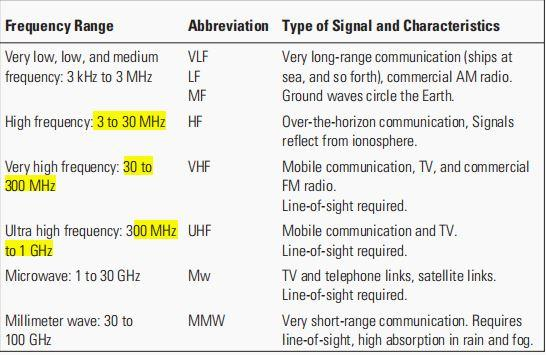

5.) The main emphasis will be on VHF, UHF and low-micro-wave frequency ranges.

6.) Lower the frequencies larger the wave length and hence can penterate through several atmospheric layers, with minimal power loss, hence lower frequency communications although demand longer antennas, can be used even when there's no Line of Sight, and hence can be used to communicate over larger distances. Lower Frequencies are also characterised by narrow bandwidths, and hence can carry only low-rate digital signals or morse code. 

7.) VHF and UHF transmissions support enough bandwidth to carry voice, data, video signals, televisionn broadcasts too. Wideband microwave point to point links carry large blocks of multimedia signals, command and data links between UAV and control stations are also in the same band. High Frequencies have smaller wavelengths, hence smaller antennas, but they are not capable of penterrating through layers of atmosphere and hence suffer loses. To avoid it, point to point communication is the most used application of Hihger ferequency signals.

**The Concept of Decibel and its significance in TBFC&EW**

1.) Equations in dB numbers/forms are logarithmic and thus allow the comparision of very large and very small values.Since the difference between the signal strength of transmitted and received signals can be as much as 20 orders of magnitude (Txed_Strength>> Rxed_Strength) there must be common scale so as to conveniently compare and analyse signals. The dB scale is efficient in the same. Any value expressed in dB units must be a ratio (which has been converted to logarithmic form). Common examples of ratios in communication are amplifier or antenna gain and losses in circuits or in radio propagation.

2.) Non dB  numbers = Linear numbers

dB  Numbers = Logarithmic numbers

[https://youtu.be/zzu2POfYv0Y?si=CfDkjGx9Ic1H2d_p](https://youtu.be/zzu2POfYv0Y?si=CfDkjGx9Ic1H2d_p) (What are logarithms in Maths? Explained)

[https://youtu.be/_p-WyPg1sbU?si=pNcZHVIwFqPo-V1Z](https://youtu.be/_p-WyPg1sbU?si=pNcZHVIwFqPo-V1Z) (Concept of decibels Explained)

3.) Features of dB or Logarithmic Numbers 

- Multiplying Non dB numbers = Add equivalent dB numbers

- Dividing Non dB numbers = Subtract equivalent dB numbers

- Raising a Non dB number to power "x" = Multiplying equivalent dB number by "x"

- To take nth root of Non dB number = Dividing equivalent dB number by "n".

- Ratio of unity i.e 1, converts to 0 dB.When both the numerator and denominator are same, one can easily call it 0 dB.

- Given below are the dB formats of few often used ratios in TBFC & EW :

            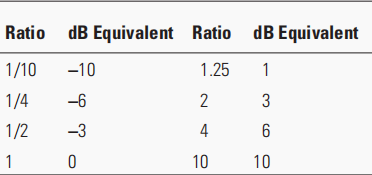

## Convert (Non dB or Linear Numbers) to (db or Logarithmic Equivalent)

% Decibels are nothing but the logarithmic equivalent of a linear number multiplied by 10
N_in_Linear =5 %enter your linear number here

N_in_Linear = 5

N_in_Log = log10(N_in_Linear); %10*log_base_10_of_N
N_in_dB = 10*N_in_Log

N_in_dB = 6.9897

## **Convert  (db or Logarithmic) to (Non dB or Linear Equivalent) **

N_in_dB = 6.9897 %enter the logarithmic number here

N_in_dB = 6.9897

N_in_Linear = 10^(N_in_dB/10) 

N_in_Linear = 5.0000

## Basic arithmetic operations using db Equivalents

clear all
Linear_numbers = [1,2,3]

Linear_numbers =      1     2     3



dB_equivalent = 10*log10(Linear_numbers)

dB_equivalent =          0    3.0103    4.7712


## Multiplication of Linear Numbers

Product_of_Linear_numbers = 10.^(sum(dB_equivalent)/(10));
Product_of_Linear_numbers = prod(Product_of_Linear_numbers)

Product_of_Linear_numbers = 6

## Division of Linear Numbers

difference = dB_equivalent(1,1);
[i,j]=size(dB_equivalent);
for i=2:numel(dB_equivalent)
    difference = difference - dB_equivalent(i);
end
difference = 10.^((difference)/(10));
Divison_of_Linear_numbers = difference

Divison_of_Linear_numbers = 0.1667

## Linear numbers raised to the power of "n"

n =3

n = 3

Linear_numbers_to_the_power_of_n = 10.^(n*dB_equivalent/(10))

Linear_numbers_to_the_power_of_n =     1.0000    8.0000   27.0000


## nth root of Linear numbers

nth_root_of_linear_number = 10.^((dB_equivalent/n)/(10))

nth_root_of_linear_number =     1.0000    1.2599    1.4422


## dB to Linear number equivalent converter

dB =-1.792 

dB = -1.7920

Equivalent_Linear_number = 10^(dB/10)

Equivalent_Linear_number = 0.6619

## Linear number to dB equivalent Converter

Linear_number =0

Linear_number = 0

dB_equivalent = 10*log10(Linear_number)

dB_equivalent = -Inf

## Watts to dBW; dBm Converter

Power_in_watts = 1

Power_in_watts = 1

dBW_equivalent = 10*log10(Power_in_watts)

dBW_equivalent = 0

Power_in_watts = (Power_in_watts/1e-3);
dBm_equivalent = 10*log10(Power_in_watts)

dBm_equivalent = 30